# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.4 面积图与折线图如何组合在一起？

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/526030551/answer/2424594088](https://www.zhihu.com/question/526030551/answer/2424594088)

# 面积图与折线图如何组合在一起？

想做成这种效果的图，就是两个变量，一个变量用阴影部分表示，一个变量用折线图表示，请问这种方法能在orgin或者excel中实现吗？或者其他方法能不能做出这种效果的图？

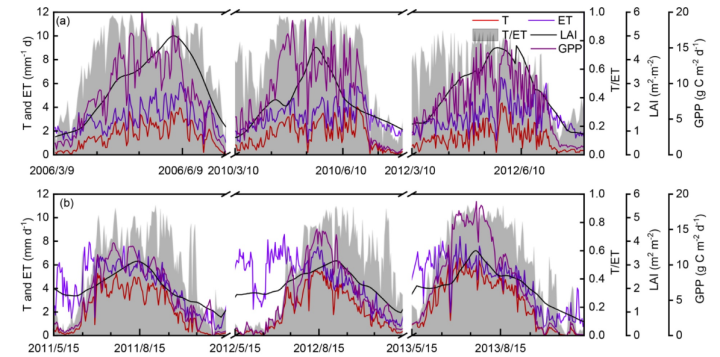

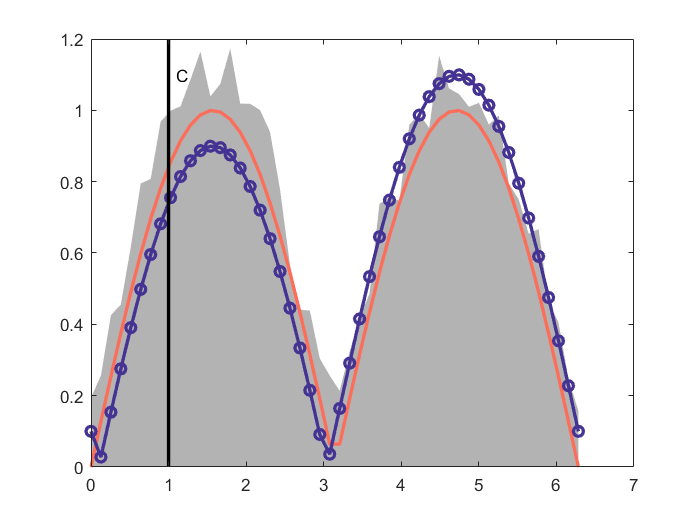

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
x = linspace(0, 2*pi, 50);
y = abs(sin(x))+ 0.2*rand(1, 50);
x = [x(1), x, x(end)];
y = [0, y, 0];
figure
% 阴影面积图
fill(x, y, [0.7, 0.7, 0.7], 'LineStyle', 'none');
% 曲线图和点线图
y = sin(x);
hold on
plot(x, abs(y), 'Color', all_colors(1, :), 'LineWidth', 2);
plot(x, abs(y - 0.1), 'o-', 'Color', all_colors(6, :), 'LineWidth', 2);
% 设置范围
ylim([0, 1.2]);
% 黑色竖线
plot([1, 1], [0, 1.2], 'k', 'LineWidth', 2);
% 文本
text(1.1, 1.1, 'C');
hold off